# Project 2 - Solar Cooker

Gia-uyen Tran and Krishna Suresh

## Question

## Method

In this model, the sun is the energy source. The sun’s rays are assumed to enter the solar cooker perpendicular to its open circular face and reflect perfectly (i.e., there is no energy loss) off of the paraboloid. Because of the unique properties of a paraboloid, these rays reflect to a point known as the focus, which is where the pot of water will be located. The radiation heats the stainless steel pot, which then heats the water via convection. This process can be modeled with the function *solar_cooker_sim, *which takes the radius of a paraboloid as its input and outputs three things:

- T, a vector with the times chosen by ode45

- M, a matrix with columns for the temperature of the pot (column 1) and the water (column 2) at each timestep, and

- boil_time, the  time in minutes that it would take for that solar cooker to bring the water water in the pot to a boil (373 K).

For the purposes of this model, the pot will be stainless steel. Its dimensions are 8cm in radius and 8cm tall with a 0.5mm thickness. For a solar cooker with a radius of 0.6 meters:

[T, M, boil_time] = solar_cooker_sim2(3.2);
plot(T, M(:,2))
ylabel("Temperature (K)")
xlabel("Time (min)")
title("Temperature change of pot of water on a 0.6m radius solar cooker")

We can now parameter sweep radius values. The radii values were chosen such that the focus was at most half a meter above the largest circular cross section of the paraboloid. The intention was to model a reasonable solar cooker design. While it would be possible to have a focus further out, it would become increasingly difficult to build a stable platform to hold to pot. Addiitonally, the focus was at least 10 centimeters away from the bottom of the cooker to ensure that the pot (8cm tall) would fit. With these guidelines in mind, the radius values were swept ranging from 0.5m to 1.5m incrementing by 0.1m each time.

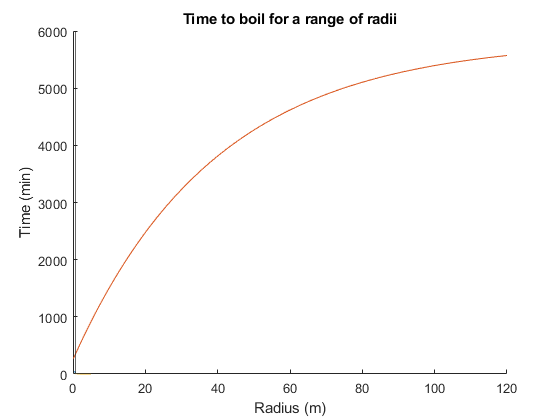

clear
sweep_range=0.5:0.1:5;
J = zeros(size(sweep_range, 2), 2);
for i=1:length(sweep_range)
    [T, M, boil_time] = solar_cooker_sim(sweep_range(i));
    J(i,:) = [sweep_range(i), boil_time];
end
plot(J(:,1), J(:,2))
xlabel("Radius (m)")
ylabel("Time (min)")
title("Time to boil for a range of radii")

The graph clearly shows that the bigger the radius of the solar cooker, the less time it takes to bring the water to boiling point. However, the shape is that of an exponential decay -- the decrease in time is much greater between a 0.5m and 0.6m radius than between a 1.2m and 1.3m radius. Thus, while increasing radius leads to faster heating, it eventually leads to diminishing returns.

However, this model does not account for the pot of water losing energy to its surrounding environment. In the function solar_cooker_sim2, the pot of water loses energy through convection between the pot and the air in addition to the convection to the water and the air.

sweep_range=0.5:0.1:1.5;
K = zeros(size(sweep_range, 2), 2);
for i=1:length(sweep_range)
    [T, M, boil_time] = solar_cooker_sim2(sweep_range(i));
    K(i,:) = [sweep_range(i), boil_time];
end

The resulting graph follows a similar curve as the first model, but the water takes noticeably longer to reach boiling point. As such, the conclusions are similar to that of the first model: the general shape of the graph indicates diminishing returns.

### Finding Material Cost of Solar Cooker

In order to find the material cost of a solar cooker, we first abstracted the volumetric shape of a paraboloid shell to a two dimensional surface. This corresponds to a cost calculation of sheets being per square meter. Using this abstraction, we calculated the surface area of the paraboloid by rotating a parabola around the y axis. 


$$$$r= \text{radius of paraboloid} $$
$$h= \text{height of paraboloid} $$
$$  \int_{-r}^{r} 2 \pi x \,ds  $$
$$ ds = \sqrt{1 + \left(\frac {dy} {dx}\right)^2} $$
Points which the parabola passes through:
$$(0,0), (-r, h), (r, h)$$
$$ 0 = a(0)^2 + b(0)+c $$
$$ c = 0 $$
$$ h = a(r)^2 + b(r)+c $$
$$ h = a(-r)^2 + b(-r)+c $$
$$2h = 2ar^2 $$
$$ a = h/r^2 $$
$$ y = \frac {h} {r^2} x^2$$
$$ \frac {dy} {dx} = \frac {2h} {r^2} x$$
$$ ds = \sqrt{1 + \left(\frac {2h} {r^2} x\right)^2}$$
$$  \int_{0}^{r} 2 \pi x \, \sqrt{1 + \left(\frac {2h} {r^2} x\right)^2} dx  $$
$$


The *paraboloid_radius_to_cost* function numerically calculates this integral to find the inner surface area of the solar cooker and multiples it by the cost per square meter. 

Parameters for paraboloid_radius_to_cost:

- Radius in meters

- Depth of solar cooker in meters

- Cost per square meter in dollars

#### Finding a cost per square meter:

cost_per_sq_m = 1

Below is a sweep displaying this relasionship between cost and radius of the solar cooker, but we will only be using this to find the cost of one solar cooker.

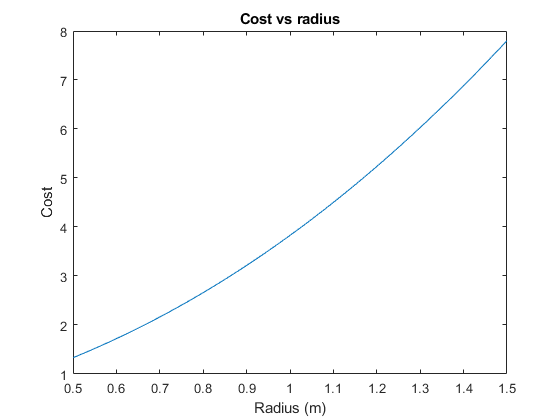

figure(3)
sweep_range=0.5:0.01:1.5;
K = zeros(size(sweep_range, 2), 2);
for i=1:length(sweep_range)
     cost = paraboloid_radius_to_cost(sweep_range(i), 0.5, cost_per_sq_m);
     K(i,:) = [sweep_range(i), cost];
end
plot(K(:,1), K(:,2))
xlabel("Radius (m)")
ylabel("Cost")

title("Cost vs radius")

## Results

figure(2)
sweep_range=0.5:0.01:1.5;
K = zeros(size(sweep_range, 2), 2);
for i=1:length(sweep_range)
    [T, M, boil_time] = solar_cooker_sim2(sweep_range(i));
    K(i,:) = [sweep_range(i), boil_time];
end
time_constrain = 15;
[min_time, min_radius_ind] = min(K(1:find(K(:,2) < time_constrain, 1),2));
min_radius = K(min_radius_ind,1)

min_radius = 0.7800

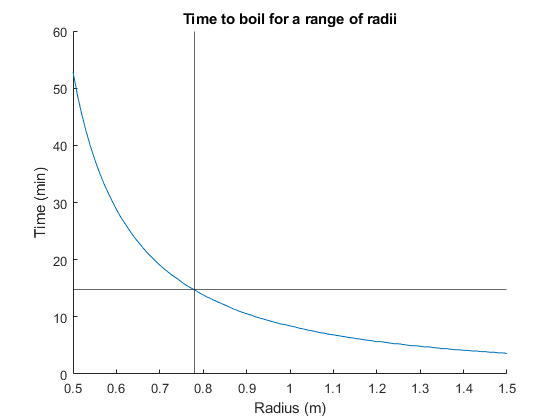

clf
hold on
plot(K(:,1), K(:,2))
xline(min_radius);
yline(min_time);
xlabel("Radius (m)")
ylabel("Time (min)")
title("Time to boil for a range of radii")

The above sweep across radii illustrates the change in time to boil as we increase the radius of the solar cooker and with a time constraint of 15 minutes, a solar cooker with a radius of X meters is the minimum size to heat water to a temperature of X K. However, we do find that as we lower our time constraint the change in radius dramatically decreases with incremental temperature changes. Therefore, our representation of the relationship between time to boil and radius is only relevant in the ranges leading up to the asymptotic end condition of the model.

Additionally, we applied the conversion between radius and predicted cost to find a dollar amount of X calculated from the surface area of the solar cooker. 

cost = paraboloid_radius_to_cost(min_radius, 0.5, 1)

cost = 2.5571

## Interpret

Overall, our results indicate water boiling times that fit the realm of reasonability and indicate a trend that is similar to the asymptotic diminishing returns we inferred would occur. Some key considerations that we found to break our representation of this system include the evaporation of water, reflection efficiency, and pot conduction. Since water will change phase at the point of boiling and carry away energy through the molecules leaving the mass, the carrying capacity of heat is much lower than what our model displays when run over long periods of time. Additionally, our assumption of perfect reflection of radiation skews our boiling times to be faster than with a physical test. Finally, we assumed a uniform heat distribution with energy flow into the pot which would more likely follow a model including conduction between the outer and inner surfaces. But, for the purposes of estimating a radius to optimally boil water within a fixed time interval, these factors more so influence the long term or proportional impacts. Therefore, our findings illustrating the non-linear relationship between time to boil and radius of a solar cooker through the high level abstraction of heat flows can effectively find the minimum cost of a solar cooker to boil water within 15 minutes.

#### References

T. V. Ramachandra, Gautham Krishnadas, Rishabh Jain, "Solar Potential in the Himalayan Landscape", International Scholarly Research Notices, vol. 2012, Article ID 203149, 13 pages, 2012. https://doi.org/10.5402/2012/203149